# SJ - laboratorium 

## Termin 1 - Karty kontrolne

20.11.2024, g. 8:00 - 10:15, s. 623, 623a.

Podsekcja:

Filip Bazarnicki 

Kacper Wach

Zadania:

1) Napisać funkcję do wizualizacji danych z próbek pomiarowych.

Wejściem funkcji jest macierz N x M zawierająca wyniki pomiarów M-próbek N-elementowych. Funkcja powinna tworzyć wykres zawierający trzy podwykresy ustawione jeden pod drugim: pierwszy do prezentacji wyników surowych próbek, drugi przedstawiający wartości średnie dla próbek (karta pomiarów wartości średniej), trzeci przedstawiający odchylenia standardowe próbek (karta pomiarów odchylenia standardowego). Oś odciętych w każdym wykresie powinna przedstawiać nr próbki, na osi rzędnych - wartości wskaźników. Przetestować funkcję na wygenerowanych danych.

**Rozwiązanie zapisano w funkcji 'lab1_zad1(A)'**

A=randn(4,5)*5+1000;A=sort(A),  mean(A), min(min(A)),

A = 1.0e+03 *

    0.9917    0.9916    1.0003    0.9953    0.9934
    0.9970    0.9939    1.0016    0.9967    0.9997
    0.9986    1.0021    1.0033    1.0013    1.0000
    1.0050    1.0024    1.0054    1.0050    1.0046


ans = 1.0e+03 *

    0.9981    0.9975    1.0027    0.9996    0.9994


ans = 991.6490

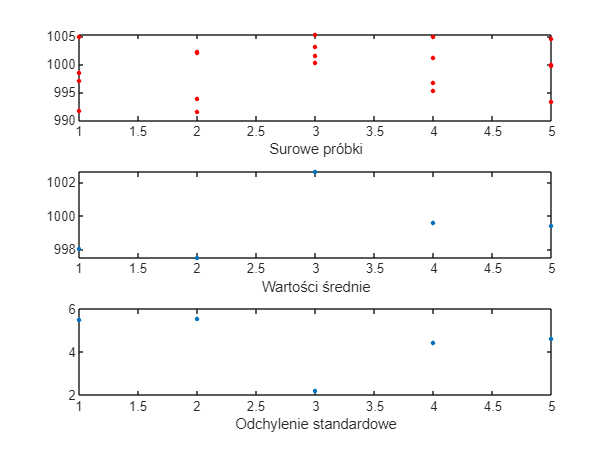


lab1_zad1(A);

2) Zapoznać się z funkcją 'boxplot'. Przetestować funkcję ‘boxplot’ używając danych symulowanych za pomocą funkcji ‘rand’, ‘randn’. Zmodyfikować napisaną powyżej funkcję wykorzystując w niej polecenie 'boxplot'.

help boxplot

 boxplot Displays box plots of multiple data samples.
    boxplot(X) produces a box plot of the data in X.  If X is a matrix there
    is one box per column, and if X is a vector there is just one box. On
    each box, the central mark is the median, the edges of the box are the
    25th and 75th percentiles, the whiskers extend to the most extreme
    datapoints the algorithm considers to be not outliers, and the outliers
    are plotted individually.  
    
    boxplot(X,G) specifies one or more grouping variables G, producing a
    separate box for each set of X values sharing the same G value or
    values.  Grouping variables must have one row per element of X, or one
    row per column of X. Specify a single grouping variable in G by using a
    vector, a character array, a cell array of character vectors, a string
    array, or a vector categorical array; specify multiple grouping
    variables in G by using a cell array of thes

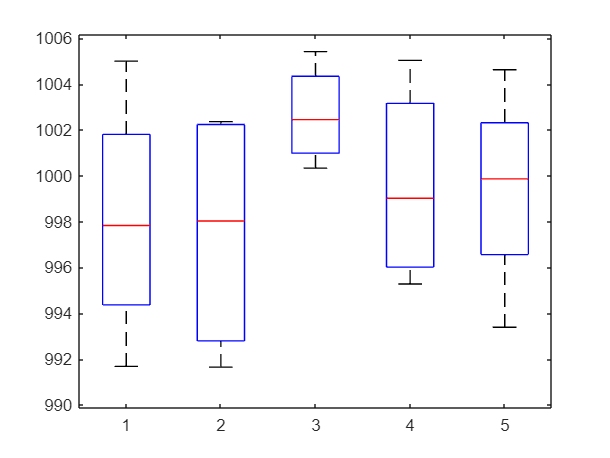

srednia = mean(A);
odchylenie  = std(A);

figure
%subplot(3,1,1)
boxplot(A)



% subplot(3,1,2)
% plot(srednia,'.', 'MarkerSize', 8)
% 
% 
% subplot(3,1,3)
% plot(odchylenie,'.', 'MarkerSize', 8)

3) Napisać funkcję wykreślającą kartę kontrolną wartości średnich wraz z dolnymi i górnymi liniami kontrolnymi. Użyć danych z tabeli 1. Wejściem funkcji jest macierz NxM zawierająca wyniki pomiarów Mpróbek

N-elementowych. Ograniczenie na N: 2 do 25, dla próbek o liczności nie występującej w tab.

dokonać interpolacji z sąsiednich danych w tabeli 1.

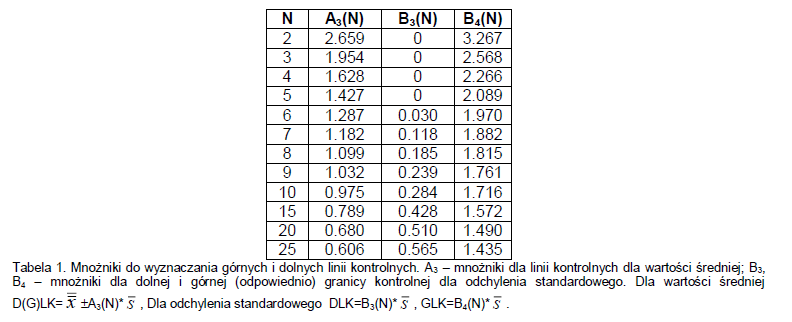pwd

Zadanie zrealizowano w postaci funkcji **cw1_zad3(A)**, którą wywołano poniżej:

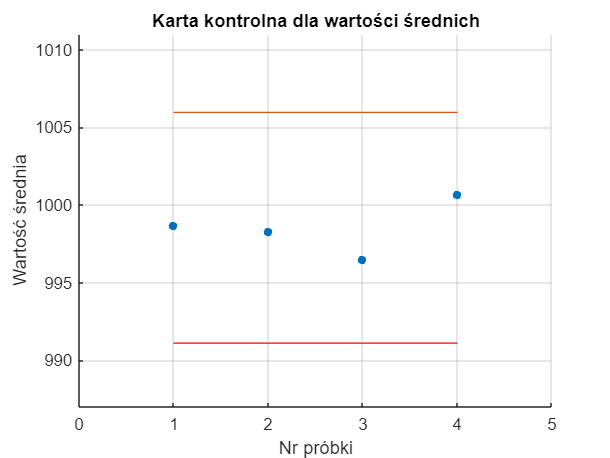

A=randn(5,4)*5+1000;
lab1_zad3(A)

4) Napisać funkcję wykreślającą kartę kontrolną odchylenia standardowego wraz z dolnymi i górnymi

liniami kontrolnymi. Użyć danych z poniższej tabeli. Wejściem funkcji jest macierz NxM zawierająca wyniki

pomiarów M-próbek N-elementowych. Ograniczenie na N: 2 do 25, dla próbek o liczności nie występującej

w tab. dokonać interpolacji z sąsiednich danych w tabeli.

Zadanie zrealizowano w postaci funkcji **cw1_zad4(A)**, którą wywołano poniżej:

A=randn(5,4)

A =     2.4245    1.8779   -0.5583   -0.2099
    0.9594    0.9407   -0.3114   -1.6989
   -0.3158    0.7873   -0.5700    0.6076
    0.4286   -0.8759   -1.0257   -0.1178
   -1.0360    0.3199   -0.9087    0.6992


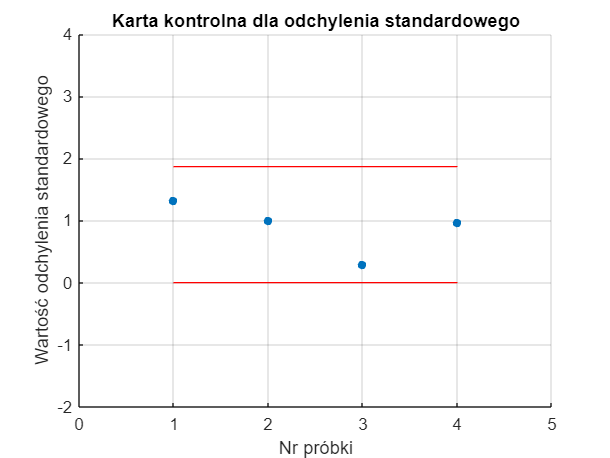

lab1_zad4(A)

5) Załóżmy, że zmienne losowe zakłócające stabilny przebieg procesu dodają się do zmiennej odpowiadającej stabilnemu, czyli uregulowanemu, procesowi. Próbka pobierana w chwili t odpowiada obserwacjom pewnej zmiennej losowej Y(t),

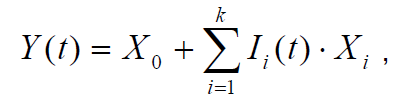

gdzie Xi pochodzi z rozkładu Fi o wartości oczekiwanej i i wariancji i

2, a funkcja wskaźnikowa I(t) ma postać: I(t)=1 z prawdopodobieństwem pi lub I(t)=0 z prawdopodobieństwem 1-pi. Jeżeli podany model

jest właściwy i mamy k możliwych wyznaczalnych przyczyn rozregulowania, to w danej próbce obecna jest jedna z 2k możliwych kombinacji zmiennych losowych odpowiadających tym przyczynom rozregulowania. Skrajnymi możliwościami spośród wszystkich 2k kombinacji są: niewystąpienie żadnej przyczyny rozregulowania oraz wystąpienie wszystkich przyczyn rozregulowania. Zakładamy, że próbki pobierane są dostatecznie rzadko, by postać zmiennej Y dla jednej próbki była niezależna od jej postaci dla innej próbki. Jednocześnie zakładamy, że każda funkcja wskaźnikowa Ii zachowuje stałą wartość (0 lub 1) w czasie pobierania jednej próbki.

W przypadku szczególnym, gdy rozkłady wszystkich zmiennych losowych są normalne, obserwowana zmienna losowa Y(t) może być przedstawiona jako:

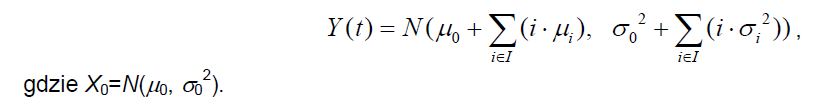

Dla opisanego powyżej modelu napisać funkcję w środowisku Matlab realizującą M-próbek N elementowych (macierz NxM) zmiennej Y dla założonej liczby k przyczyn rozregulowania procesu X0, prawdopodobieństw realizacji zmiennych zakłócających Xi. Założyć, że proces odstawowy oraz procesy zakłócające mają rozkład normalny o zadanych wartościach oczekiwanych i wariancjach.

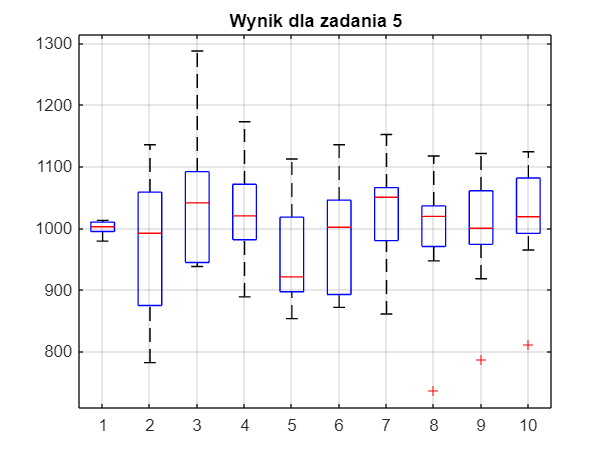

mi0 = 1000;
sigma0 = 10;
pz = [0 0.7];
miz = [-250 0];
sigmaz = [0 100];
M=10;
N=10;

A=lab1_zad5(mi0,sigma0,pz,miz,sigmaz,M,N);


figure;boxplot(A);title('Wynik dla zadania 5');grid on

## Funkcje realizujące poszczególne zadania

function wy=lab1_zad1(A)

[N,M] = size(A);

srednie = mean(A);
odchylenieStandard  =std(A);

figure
subplot(3,1,1)
plot(1:M,A,'.','Color', 'r', 'MarkerSize', 8)
xlabel('Surowe próbki')

subplot(3,1,2)
plot(1:M,srednie,'.', 'MarkerSize', 8)
xlabel('Wartości średnie')
% wizualizacja danych z macierzy A
% A: N x M - zawiera M-próbek po N elementów każda

subplot(3,1,3)
plot(1:M,odchylenieStandard,'.', 'MarkerSize', 8)
xlabel('Odchylenie standardowe')

end % of zad 1


function wy=lab1_zad3(A)

[n,m] = size(A);

% Tabela ze współczynnikami do zad. 3:
N=[2 3 4 5 6 7 8 9 10 15 20 25];
A3=[2.659 1.954 1.628 1.427 1.287 1.182 1.099 1.032 0.975 0.789 0.680 0.606];

interpol = interp1(N,A3,n);

  figure 
    hold on
    grid on
    title('Karta kontrolna dla wartości średnich');
    plot(mean(A),'.', 'MarkerSize',15);
    xlim([0 m+1]);
    ylim([floor(min(min(A))) ceil(max(max(A)))]);
    xlabel('Nr próbki');
    ylabel('Wartość średnia');
    odchylenie=mean(std(A));
    srednia=mean(mean(A));
    nr=1:m;
    plot(nr,ones(size(nr))*(srednia+interpol*odchylenie),nr, ones(size(nr))*(srednia-interpol*odchylenie), 'r')
    


%xmm = mean(mean(A));

end % zadanie 3

function wy=lab1_zad4(A)

[n,m] = size(A);

%  Tabela ze współczynnikami do zad. 4.
N=[2 3 4 5 6 7 8 9 10 15 20 25];
B3=[0 0 0 0 0.030 0.118 0.185 0.239 0.284 0.428 0.510 0.565];
B4=[3.267 2.568 2.266 2.089 1.970 1.882 1.815 1.761 1.716 1.572 1.490 1.435];

interB3 = interp1(N,B3,n);

interB4 = interp1(N,B4,n);
odchylenie=mean(std(A));

nr=1:m;
figure
hold on
grid on
title('Karta kontrolna dla odchylenia standardowego');
std_values = std(A); % Obliczenie odchylenia standardowego
plot(std_values, '.', 'MarkerSize', 15);
xlim([0 m+1]);
ylim([floor(min(std_values)-2) ceil(max(std_values)+2)]); % Automatyczne skalowanie osi Y
xlabel('Nr próbki');
ylabel('Wartość odchylenia standardowego');
plot(nr, ones(size(nr))*(interB3*odchylenie), 'r');
plot(nr, ones(size(nr))*(interB4*odchylenie), 'r');


%Vq = interp1(X,V,Xq) interpolates to find Vq, the values of the
%    underlying function V=F(X) at the query points Xq.

end % zad 4

function A=lab1_zad5(mi0,sigma0,pz,miz,sigmaz,M,N)

xo = mi0 + randn(N,M)*sigma0;

dlu = length(pz);

A=[];
for j=1:M
    I=zeros(dlu,1);
    for i=1:dlu
        if rand<pz(i)
            I(i)=1;
        end
    end

Z = [];

for i=1:dlu
    Z=[Z (randn(N,1)*sigmaz(i)+miz(i))*I(i)];
end
    if dlu == 1
        K = Z;
    else
        K = (sum(Z'))';
    end
A = [A, K];
end
A = xo + A;
end